# Data Analysis

## Introduction

The data file contains a list of weather events that occurred in the United States in 2013. The events have been categorized by type and the state in which they occurred. There is also information about 

- damage costs

- number of resulting injuries 

- location of some of the events

StormEvents = importfile("StormEvents_2014.csv");


## Reorder months

month = ["January","February","March","April","May","June","July","August","September","October","November","December"];
StormEvents2013.Month = reordercats(StormEvents2013.Month,month)

StormEvents2013 = 59465×23 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                      

## Visualize raw data

Create a heat map to look at the frequency of each event type by month.

Count of events by type and month

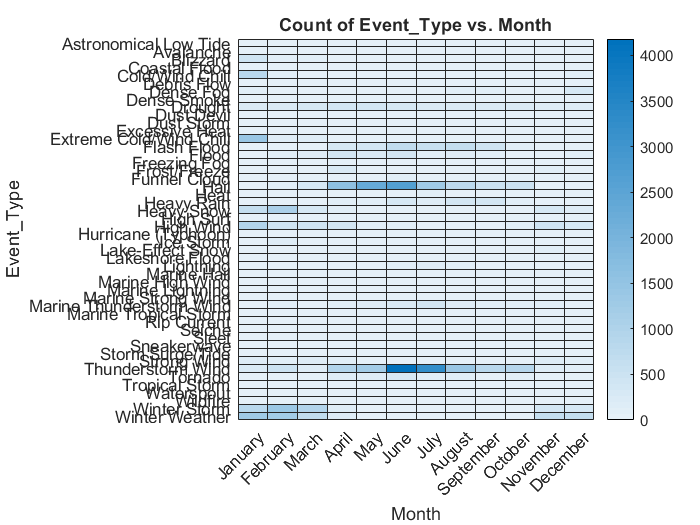

heatmap(StormEvents2013,"Month","Event_Type");

## Explore Hail and Thunderstorm Wind

There is a higher occurrence of Hail and Thunderstorm Wind in the summer months. Further analysis will see if there is a relationship between these two events.

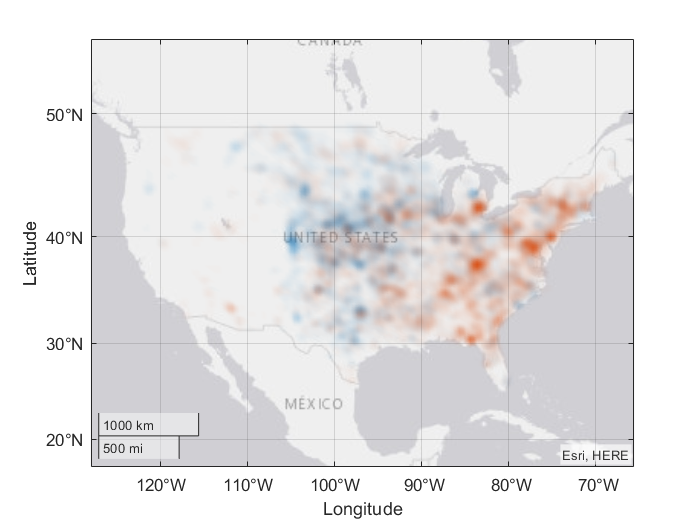

%Creating a new plot - geodensity
Hind = StormEvents2013.Event_Type=="Hail";
geodensityplot(StormEvents2013.Begin_Lat(Hind),StormEvents2013.Begin_Lon(Hind))
% Just show continental US
geolimits([17.0 55.2],[-128.0 -65.6])

% Add Thunderstorm Wind to see if they are related.
hold on
TWind = StormEvents2013.Event_Type=="Thunderstorm Wind";
geodensityplot(StormEvents2013.Begin_Lat(TWind),StormEvents2013.Begin_Lon(TWind))
hold off


% When looking across all states, there does not appear to be a relationship between hail and thunderstorm wind. Hail appears to be concentrated in the central United States while thunderstorm wind is concentrated in the eastern United States. However, there still may be some storms where both events occurred. Looking at events in a single state may show this.



## State

The geodenisty plot shows some potential overlapping hail and thunderstorm wind events in Texas.

state = "FLORIDA"

state = "FLORIDA"

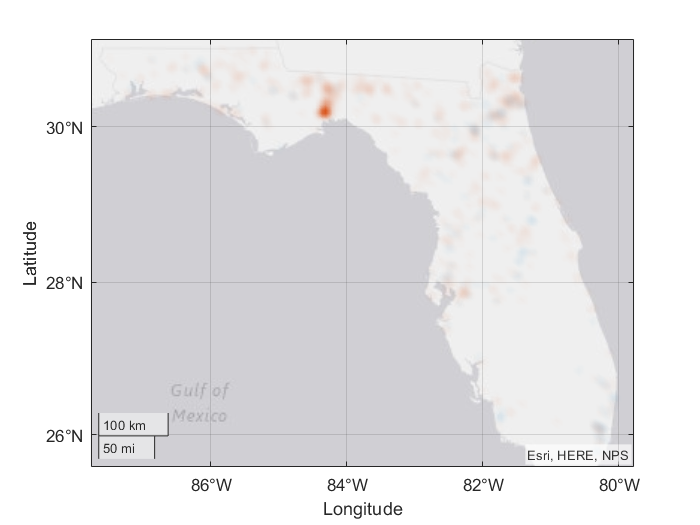


% Creating a new plot - geodensity
Hind = StormEvents2013.Event_Type=="Hail" & StormEvents2013.State==state;
geodensityplot(StormEvents2013.Begin_Lat(Hind),StormEvents2013.Begin_Lon(Hind))

% Add Thunderstorm Wind to see if they are related.
hold on
TWind = StormEvents2013.Event_Type=="Thunderstorm Wind" & StormEvents2013.State==state;
geodensityplot(StormEvents2013.Begin_Lat(TWind),StormEvents2013.Begin_Lon(TWind))
hold off


% While it appears most of the events are unrelated, some of the events do overlap. The large concentration at the top is near Amarillo, Texas. Looking at that cluster of events may show a relationship.



## Location

Both hail and thunderstorm wind events contain latitude and longitude values. Use this to select events that occurred within a specified distance of Amarillo. The coordinates for Amarillo, TX were obtained online.

Lat = 35.221996;
Lon = -101.831299;

% Distance from Amarillo can be computed using the Haversine formula:
% 

https://www.movable-type.co.uk/scripts/latlong.html

%    a=sin^2((lat1-lat2)/2) + cos(lat1)*cos(lat2)*sin^2((lon1-lon2)/2)
%    c=2*atan2(a^0.5, (1-a)^0.5)
%    d=R*c
dLat = StormEvents2013.Begin_Lat - Lat;
dLon = StormEvents2013.Begin_Lon - Lon;

% Haversine formula

[Haversine formula](https://www.movable-type.co.uk/scripts/latlong.html)

R = 6371; % earth's radius, kilometers
a = sind(dLat/2).^2 + cosd(StormEvents2013.Begin_Lat).*cosd(StormEvents2013.End_Lat).*sind(dLon/2).^2;
c = 2*atan2(sqrt(a),sqrt(1-a));

% Add distance to data table
StormEvents2013.Dist_m = R*c; % kilometers

% Select all hail and thunderstorm wind events that occurred within 8 km (~5 miles) of Amarillo, TX.
dist = 20; % kilometers
events = StormEvents2013((StormEvents2013.Event_Type=="Hail" | ...
    StormEvents2013.Event_Type=="Thunderstorm Wind") & ...
    StormEvents2013.Dist_m < dist,:)

events = 59×24 table
    EpisodeID     Event_ID     State    Year      Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                         

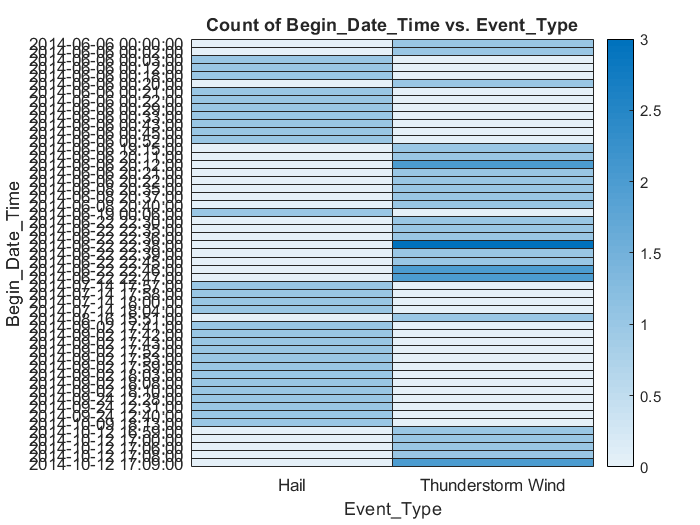


events.Event_Type = removecats(events.Event_Type); % remove empty categories
heatmap(events,"Event_Type","Begin_Date_Time");

% So far, the analysis has only used location to identify a potential relationship between hail and thunderstorm wind events. However, the events must also occur around the same time to be related. Since the number of events has been reduced by the filtering, the simplest way of visualizing location and date is with a heatmap of event type and date.



## Conclusion

The main contributing factor in the formation of hail is wind. It would therefore be reasonable to expect some relationship between hail and thunderstorm wind events. This preliminary investigation into these two events would suggest that, at least in this data set, there is not a strong relationship.

A comparison of the events by concentration shows most hail events occur in the central United States while most thunderstorm wind events occur in the east. There are exceptions, but it is necessary to look at individual storms to identify potential relationships.

One such storm was found to hit the Amarillo, Texas area on May 28, 2013. Eight thunderstorm wind events were recorded between 16:16 and 17:11. Then starting at 22:35, nine hail events were recorded, with the last one starting at 23:14.

Additional work is necessary to determine if the thunderstorm wind events did in fact contribute to the hail events.